% reset
clc; clear; close all;

# Discrete Fourier Transform using MATLAB fft(x)

The MATLAB® environment provides the functions `fft` and `ifft` to compute the discrete Fourier transform and its inverse, respectively. For the input sequence *x* and its transformed version *X* (the discrete-time Fourier transform at equally spaced frequencies around the unit circle), the two functions implement the relationships


$$X(k+1)=\sum_{n=0}^{N-1}x(n+1)W_N^{kn}$$


and


$$x(n+1)={1\over N}\sum_{k=0}^{N-1}X(k+1)W_N^{-kn}.$$


In these equations, the series subscripts begin with 1 instead of 0 because of the MATLAB vector indexing scheme, and


$$W_N=e^{-j2\pi \frac{k}{N}}.$$


From the [fft documentation page](https://www.mathworks.com/help/matlab/ref/fft.html), [`Y`](https://www.mathworks.com/help/matlab/ref/fft.html#f83-998360-Y) `= fft(`[`X`](https://www.mathworks.com/help/matlab/ref/fft.html#f83-998360-X)`)` computes the [discrete Fourier transform](https://www.mathworks.com/help/matlab/ref/fft.html#buuutyt-6) (DFT) of `X` using a **fast Fourier transform** (FFT) algorithm. `Y` is the same size as `X`. The FFT algorithms are based on a library named [FFTW](https://www.fftw.org/)

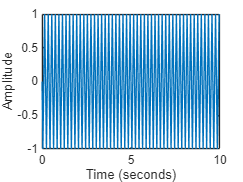

% Code from MATLAB openExample('matlab/FourierTransformsExample')

Ts = 0.05;
t = 0:Ts:10-Ts;
x = sin(2*pi*15*t) + sin(2*pi*20*t);
plot(t,x)
xlabel('Time (seconds)')
ylabel('Amplitude')

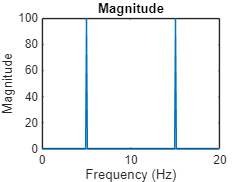


y = fft(x);
fs = 1/Ts;
f = (0:length(y)-1)*fs/length(y);

plot(f,abs(y))
xlabel('Frequency (Hz)')
ylabel('Magnitude')
title('Magnitude')

This toolbox also includes functions for the two-dimensional FFT and its inverse, `fft2` and `ifft2`. These functions are useful for two-dimensional signal or image processing. The goertzel function, which is another algorithm to compute the DFT, also is included in the toolbox. This function is efficient for computing the DFT of a portion of a long signal.

# Information for MATLAB fft(x)

% type 'edit fft' in the command window, and fft.m is opened

The code in fft.m is shown below, 

%FFT Discrete Fourier transform.
%   FFT(X) is the discrete Fourier transform (DFT) of vector X.  For
%   matrices, the FFT operation is applied to each column. For N-D
%   arrays, the FFT operation operates on the first non-singleton
%   dimension.
%
%   FFT(X,N) is the N-point FFT, padded with zeros if X has less
%   than N points and truncated if it has more.
%
%   FFT(X,[],DIM) or FFT(X,N,DIM) applies the FFT operation across the
%   dimension DIM.
%   
%   For length N input vector x, the DFT is a length N vector X,
%   with elements
%                    N
%      X(k) =       sum  x(n)*exp(-j*2*pi*(k-1)*(n-1)/N), 1 <= k <= N.
%                   n=1
%   The inverse DFT (computed by IFFT) is given by
%                    N
%      x(n) = (1/N) sum  X(k)*exp( j*2*pi*(k-1)*(n-1)/N), 1 <= n <= N.
%                   k=1
%
%   See also FFT2, FFTN, FFTSHIFT, FFTW, IFFT, IFFT2, IFFTN.

%   Copyright 1984-2005 The MathWorks, Inc.

%   Built-in functionhttps://en.wikipedia.org/wiki/File:DIT-FFT-butterfly.svg.

# Coding a FFT algorithm using radix-2 DIT apporach

Radix-2 FFT algorithms simply dividing the DFT of length N into two DFTs of length N/2 each, and iterating, until N smaller or equal to 1. Decimation-in-time (DIT) means the process is applied to the time-domain samples (input data). 

By understanding how it works, the length of input data should be a power of 2 for the splitting process. Phase shift need to perform on the odd DFTs when combing the results. 

function X = myFFT(x)
    N = length(x);
    
    if N <= 1
        X = x;
        return;
    end
    
    % zero-padding to adjust the length to a power of 2
    nextPow2 = 2^nextpow2(N);
    x = [x, zeros(1, nextPow2 - N)]; 

    % divide and conquer
    even = myFFT(x(1:2:end));
    odd = myFFT(x(2:2:end));

    X = zeros(1, N);
    for k = 0:(N/2 - 1)
        % Twiddle factor for phase shift on odd DFTs
        t = exp(-2*pi*1i*k/N) * odd(k+1); 
        % Positive Frequencies
        X(k+1) = even(k+1) + t;
        % Negative Frequencies
        X(k+1+N/2) = even(k+1) - t;
    end
end

Testing the myFFT(x) using the same input

Ts = 0.05;
t = 0:Ts:10-Ts;
x = sin(2*pi*15*t) + sin(2*pi*20*t);
plot(t,x)
xlabel('Time (seconds)')
ylabel('Amplitude')

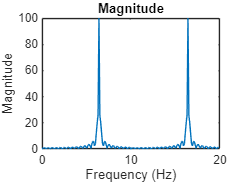

y = myFFT(x);
fs = 1/Ts;
f = (0:length(y)-1)*fs/length(y);

plot(f,abs(y))
xlabel('Frequency (Hz)')
ylabel('Magnitude')
title('Magnitude')

# Create Simulink Model

openExample('dsp/TransformTimeDomainDataIntoFrequencyDomainExample')